# Steering Control (sandbox)

#### SEED Lab                Alex Curtis

*Upload the stepResponse code to the Arduino before running.*

*PWM Frequency of the arduino: 490 Hz*

## Summary

This live script does the following:

- Communicates with the Arduino over serial

- Runs two experiments that show the characteristics of how the robot drives in a straight path and how it rotates

- Validates the experimental step response data from the Arduino

- Filters noise from the data

- Analyzes the data to determine the transfer functions of the robot

- Validates the transfer functions graphically

- Creates a controller for each transfer function using the transfer functions 

- Outputs the Kp, Ki, and Kd constants for each controller in a format that can be easily implemented in the Arduino

#### Important Variables

#### $\dot{\rho}_d$    (rho dot)             

The forward velocity of the robot (inches/sec) 

#### $\rho_d$    (rho)

The forward position of the robot  (inches)

#### $\dot{\phi}$      (phi dot)   

The angular velocity of the robot (radians/sec)

#### $\phi$      (phi)

The angular position of the robot (radians)

#### Important Equations

### 
$$\overline{V}_{a} = V_{a,1} + V_{a,2}$$


$\overline{V}_a$ is the sum of the left and right motor voltage commands. 

In the range [-400, 400] with 400 representing full forward speed

#### 
$$\Delta{V}_{a} = V_{a,1} - V_{a,2}$$


$\Delta V_a$ is the difference between the left and right motor voltage commands. 

In the range [-400,400] with 400 representing spinning clockwise at full speed 

#### Transfer functions to find:

### 
$$G_{\rho}(s) = \frac{\rho(s)}{\overline{V}_a(s)}$$


Forward position to the combined voltage commands

### 
$$G_{\phi}(s) = \frac{\phi(s)}{\Delta V_a(s)}$$


Angular position to the difference between the voltage commands

load("Experiments/RobotContolFinal.mat")

## Verify the velocity data from the Arduino

The values sent from the Arduino aren't as consistent as what Matlab can do.

WHEEL_RADIUS = 2.935;              % Radius of wheel in inches
WHEELBASE = 13.625;
rho_dot1(k,1) = 0;
phi_dot1(k,1) = 0;
rho_dot2(k2,1) = 0;
phi_dot2(k2,1) = 0;
CONVERSION = (WHEEL_RADIUS*2.0*pi)/3200;
for i = 2:k
    rho_dot1(i,1) = CONVERSION*(exp1.posR(i) - exp1.posR(i-1) + exp1.posL(i) - exp1.posL(i-1))/(2.0*(exp1.time(i)-exp1.time(i-1)));
    phi_dot1(i,1) = CONVERSION*(exp1.posL(i) - exp1.posL(i-1) - exp1.posR(i) + exp1.posR(i-1))/(WHEELBASE*(exp1.time(i)-exp1.time(i-1)));
end

for i = 2:k2
    rho_dot2(i,1) = CONVERSION*(exp2.posR(i) - exp2.posR(i-1) + exp2.posL(i) - exp2.posL(i-1))/(2.0*(exp2.time(i)-exp2.time(i-1)));
    phi_dot2(i,1) = CONVERSION*(exp2.posL(i) - exp2.posL(i-1) - exp2.posR(i) + exp2.posR(i-1))/(WHEELBASE*(exp2.time(i)-exp2.time(i-1)));
end

exp1.newRho = rho_dot1;
exp1.newPhi = phi_dot1;
exp2.newRho = rho_dot2;
exp2.newPhi = phi_dot2;

### Compare the data Matlab calculated with what the Arduino sent

% t = tiledlayout(2,1,'TileSpacing','Compact','Padding','tight');
% title(t,'Arduino Vs. Matlab')
% 
% nexttile;
% plot(exp1.time,exp1.fVel,exp1.time,exp1.newRho);
% title('Exp 1 Forward Vel');
% ylabel('Forward Velocity (in/s)');
% grid on;
% 
% nexttile;
% plot(exp2.time, exp2.rVel,exp2.time,exp2.newPhi);
% title('Exp 2 Rotational Velocity');
% legend('Arduino','Matlab','Location','east');
% ylabel('Angular Velocity (rad/s)');
% grid on
% 
% xlabel('Time (s)')

### Clean and Scale the velocity data

Smoothing the velocity data gets rid of any noise that might mess up the resulting transfer functions.

new1 = exp1;
new2 = exp2;

% Smooth input data
smoothedRho = smoothdata(exp1.newRho,"lowess","SmoothingFactor",0.4,...
    "SamplePoints",exp1.time);
new1.newRho = smoothedRho;

% Smooth input data
smoothedPhi = smoothdata(exp2.newPhi,"lowess","SmoothingFactor",0.25,...
    "SamplePoints",exp2.time);
new2.newPhi = smoothedPhi;

max motor.setM1Speed() command = 400

Since the motor command sum is a number out of 400, I need to divide the forward velocity by 400 to get a unit step response.

The maximum motor command difference is 400, corresponding to -400 and 400 on each motor. The rotational velocity needs to be divided by 400

%new1.newRho = new1.newRho/400; new2.newPhi = new2.newPhi/400;

## Determine K and sigma for each experiment

Find the steady state velocity of the motor (K)

K_rho = new1.newRho(new1.time > 0.4); K_phi = new2.newPhi(new2.time > 0.4);
K_rho = mean(K_rho), K_phi = mean(K_phi)

K_rho = 19.4195

K_phi = 2.8783

#### Find 0.64 * K and the time constant to find the values of sigma.

% Find 0.64K
K_rho64 = 0.64*K_rho;
K_phi64 = 0.64*K_phi;

% Find the closest match to 0.64K in each set of data
[~,idxRho] = min( abs(new1.newRho-K_rho64) );
magAt64K_rho = new1.newRho(idxRho);
[~,idxPhi]=min(abs(new2.newPhi-K_phi64));
magAt64K_phi=new2.newPhi(idxPhi);

% 0.64K corresponds to the location of the time constant (1/sigma)
TC_rho = new1.time(new1.newRho == magAt64K_rho)

TC_rho = 0.0800

TC_phi = new2.time(new2.newPhi == magAt64K_phi)

TC_phi = 0.0800


% We found sigma!
sigmaRho = 1/TC_rho;
sigmaPhi = 1/TC_phi;

#### Plot the processed data (motor unit step response)

% t2 = tiledlayout(1,2,"TileSpacing","compact",'Padding','tight');
% xlabel(t2, 'Time (s)')
% ylabel(t2, 'Velocity')
% title(t2, 'Robot Step Responses')
% 
% nexttile
% plot(new2.time,new2.newPhi)
% title('Rotational')
% yline(magAt64K_phi,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
% xline(TC_phi,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')
% 
% nexttile
% plot(new1.time,new1.newRho)
% title('Forward')
% yline(magAt64K_rho,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
% xline(TC_rho,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

## Create the velocity and position transfer functions

With the sigma and K values for each experiment, I can create first order transfer functions that represent the response of the robot

s = tf('s');

% Find the velocity transfer functions
rho_velTF = K_rho*(sigmaRho)/(s+sigmaRho);
rho_velTF.InputName = "Command Sum";
rho_velTF.OutputName = "Forward Velocity";
rho_velTF.OutputUnit = "inches/s"

rho_velTF =
 
  From input "Command Sum" to output "Forward Velocity":
   242.7
  --------
  s + 12.5
 
Continuous-time transfer function.




phi_velTF = K_phi*(sigmaPhi)/(s+sigmaPhi);
phi_velTF.InputName = "Command Difference";
phi_velTF.OutputName = "Rotational Velocity";
phi_velTF.OutputUnit = "rad/s"

phi_velTF =
 
  From input "Command Difference" to output "Rotational Velocity":
   35.98
  --------
  s + 12.5
 
Continuous-time transfer function.




% Position is the integral of velocity, and 1/s represents an integral.
rho_posTF = rho_velTF*(1/s);
rho_posTF.InputName = "Command Sum";
rho_posTF.OutputName = "Forward Position";
rho_posTF.OutputUnit = "inches";

phi_posTF = phi_velTF*(1/s);
phi_posTF.InputName = "Command Difference";
phi_posTF.OutputName = "Rotational Position";
phi_posTF.OutputUnit = "radians";

#### Turn the generated transfer functions into coefficient arrays I can use in Simulink

posNum_rho = rho_posTF.Numerator;       % Find the numerator coefficients
posNum_rho = posNum_rho{1};             % Convert the numerator to a the right form
posDen_rho = rho_posTF.Denominator;     % Find the denominator coefficients
posDen_rho = posDen_rho{1};             % Convert the denominator to a the right form

velNum_rho = rho_velTF.Numerator;       % Find the numerator coefficients
velNum_rho = velNum_rho{1};             % Convert the numerator to a the right form
velDen_rho = rho_velTF.Denominator;     % Find the denominator coefficients
velDen_rho = velDen_rho{1};             % Convert the denominator to a the right form

posNum_phi = phi_posTF.Numerator;       % Find the numerator coefficients
posNum_phi = posNum_phi{1};             % Convert the numerator to a the right form
posDen_phi = phi_posTF.Denominator;     % Find the denominator coefficients
posDen_phi = posDen_phi{1};             % Convert the denominator to a the right form

velNum_phi = phi_velTF.Numerator;       % Find the numerator coefficients
velNum_phi = velNum_phi{1};             % Convert the numerator to a the right form
velDen_phi = phi_velTF.Denominator;     % Find the denominator coefficients
velDen_phi = velDen_phi{1};             % Convert the denominator to a the right form

## Compare the velocity transfer functions with the actual velocity of the robot

The closer they match, the more accurately the transfer functions represent the robot

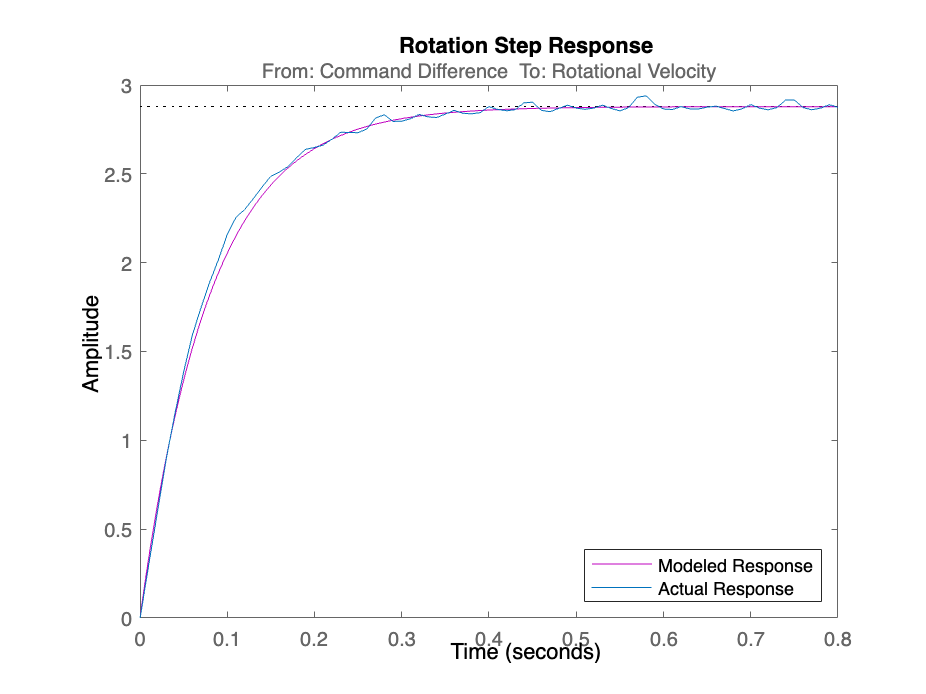

figure
stepplot(phi_velTF,'m')
hold on
plot(new2.time,new2.newPhi)
title("Rotation Step Response")
legend('Modeled Response','Actual Response','Location','southeast')
hold off

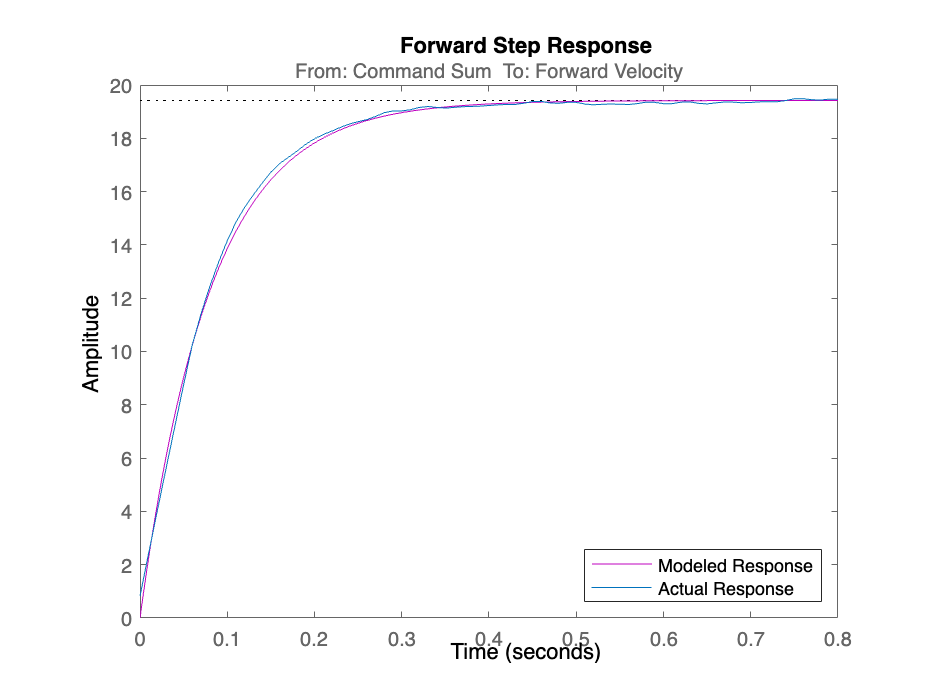


stepplot(rho_velTF,'m')
hold on
plot(new1.time,new1.newRho)
title("Forward Step Response")
legend('Modeled Response','Actual Response','Location','southeast')
hold off

figure

## Design controllers to regulate position

### Make a controller for forward position (rho)

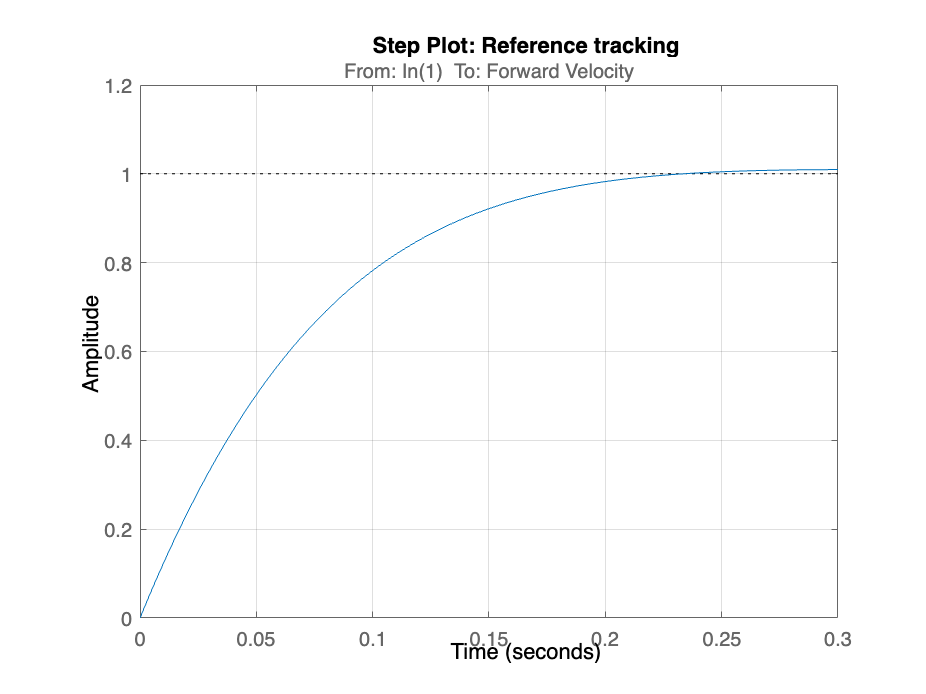

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.138446;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.830919;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[C,pidInfo3] = pidtune(rho_velTF,'PI',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response2 = getPIDLoopResponse(C,rho_velTF,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response2

### Make a controller for angular position (phi)

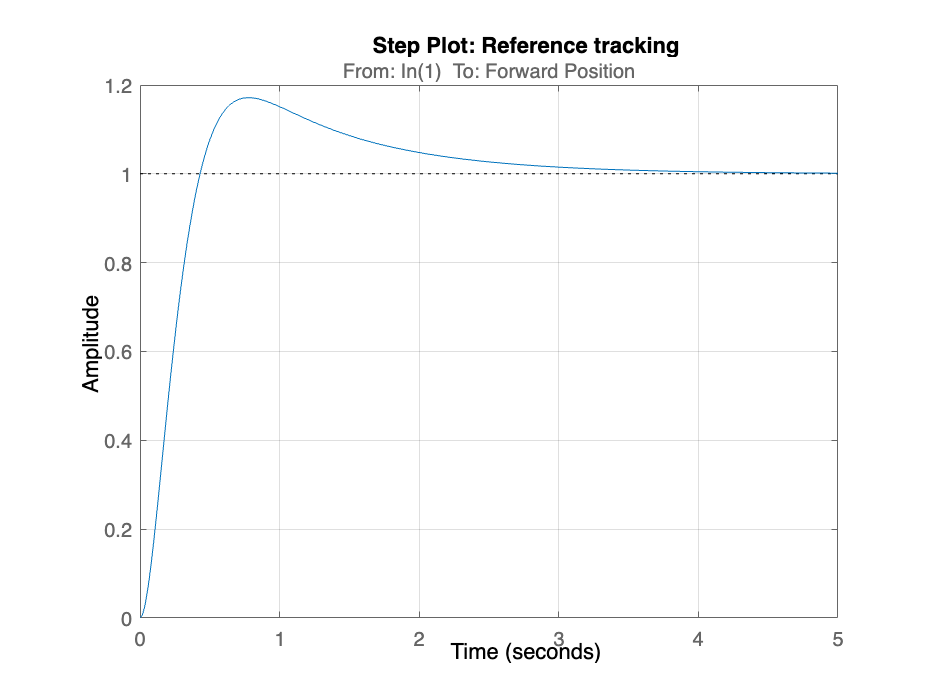

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc4 = 2/0.494303;

% PID tuning algorithm for linear plant model
[C_phi,pidInfo2] = pidtune(rho_posTF,'PI',wc4);

% Clear Temporary Variables
clear wc4

% Get desired loop response
Response = getPIDLoopResponse(C_phi,rho_posTF,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response

### Display the Kp, Ki, and Kd values for each new controller

KP_rho = C_rho.Kp; KI_rho = C_rho.Ki; KD_rho = C_rho.Kd;
KP_phi = C_phi.Kp; KI_phi = C_phi.Ki; KD_phi = C_phi.Kd;
fprintf('const float KP_RHO = %f, KI_RHO = %f, KD_RHO = %f;\n',KP_rho, KI_rho,KD_rho)

const float KP_RHO = 41.507628, KI_RHO = 0.000000, KD_RHO = 0.000000;


fprintf('const float KP_PHI = %f, KI_PHI = %f, KD_PHI = %f;\n',KP_phi, KI_phi,KD_phi)

const float KP_PHI = 0.214160, KI_PHI = 0.185192, KD_PHI = 0.000000;
